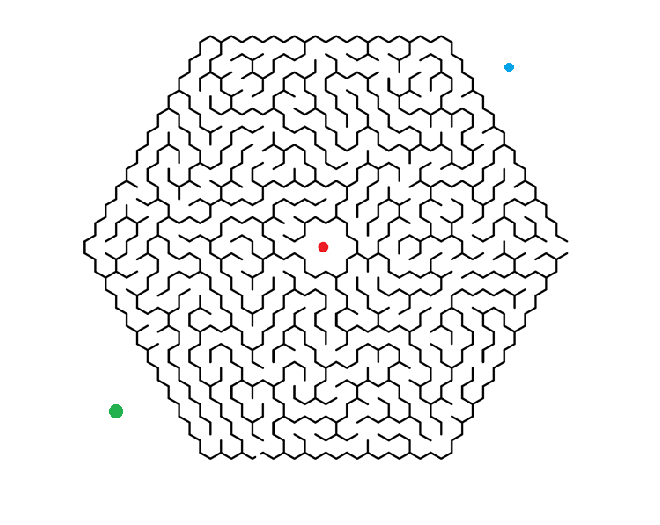

I = imread("Laberint.png");
%Igray = rgb2gray(I);

%Reconstrucció
imshow(I);

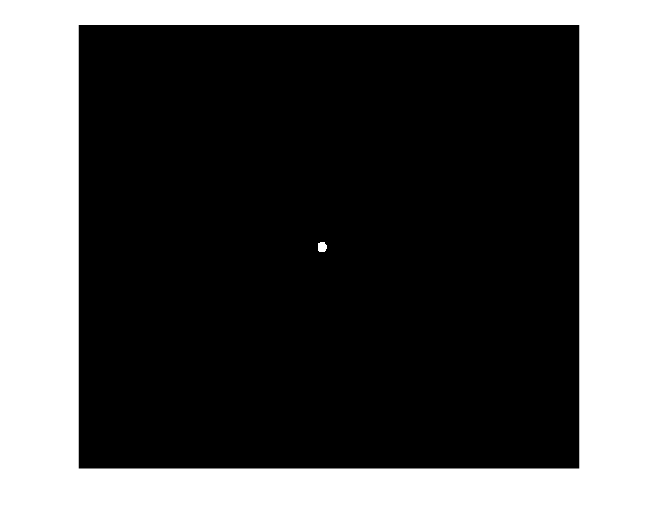

red = I(:,:,1) > 128;
green = I(:,:,2) > 128;
blue = I(:,:,3) > 128;
seed = red.*(1-green).*(1-blue);
greenDot = (1-red).*green.*(1-blue);
blueDot = (1-red).*green.*blue;
imshow(seed);

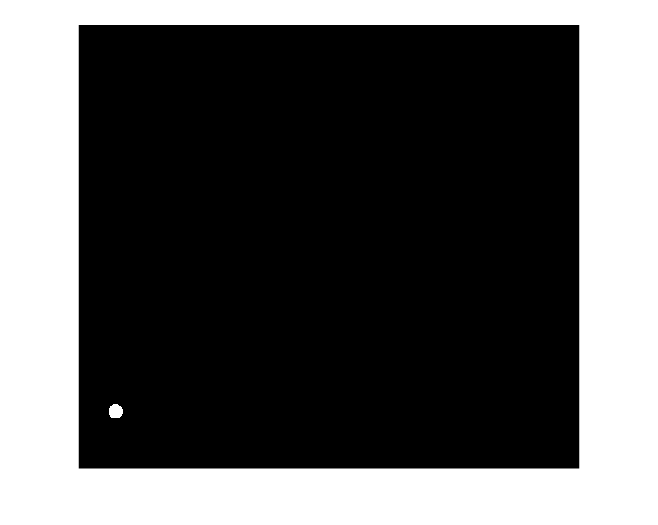

imshow(greenDot);

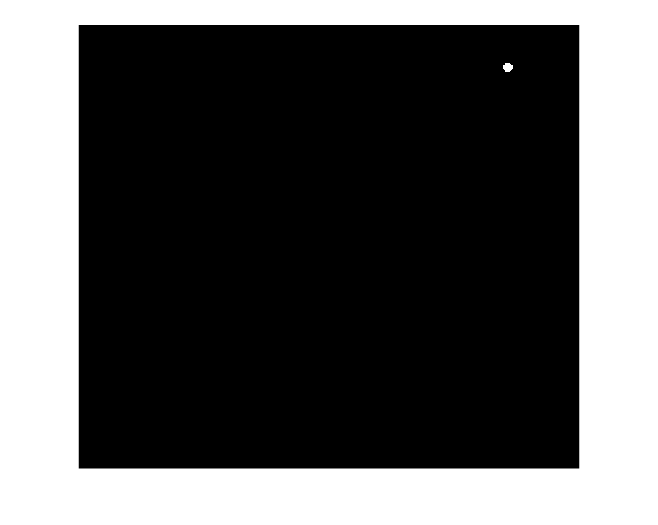

imshow(blueDot);

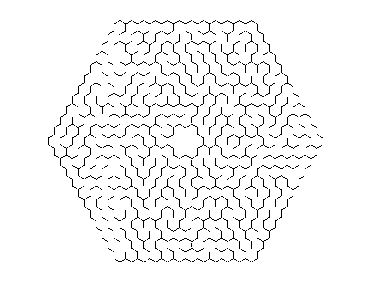

lab = I(:,:,1) < 32 & I(:,:,2) < 32 & I(:,:,1) < 32;
lab = 1-lab;
imshow(lab)


SE = strel("disk",1);
s1 = seed;

i = 0;
sumG = 0;
sumB = 0;

dist = im2double(seed);
while sumG + sumB == 0
    s1 = imdilate(s1,SE) & lab;
    sumG = sum(sum(s1&greenDot));
    sumB = sum(sum(s1&blueDot));
    i = i+1;
    dist = dist + s1;
end
i

i = 1441

sumG = 3

sumB = 0

dist =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

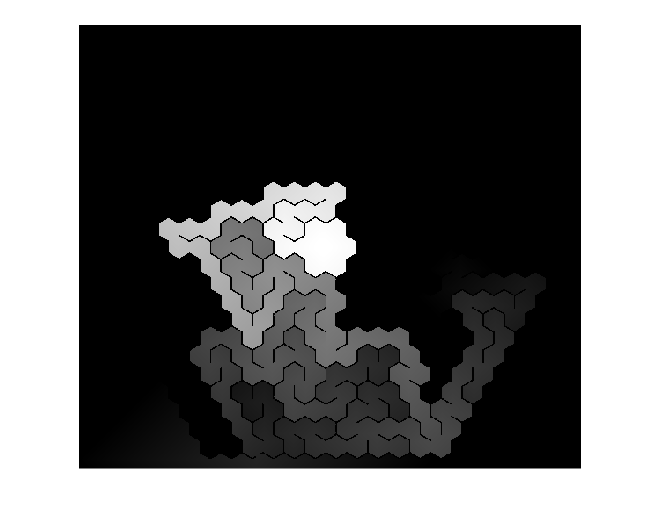

sumG
sumB
imshow(dist,[]);


s2 = greenDot;
sumR = 0;
i = 0;
dist2 = im2double(greenDot);
while sumR == 0
    s2 =imdilate(s2,SE) & lab;
    sumR = sum(sum(s2&seed));
    i = i+1;
    dist2 = dist2 + s2;
end

i

i = 1441

sumR

sumR = 1

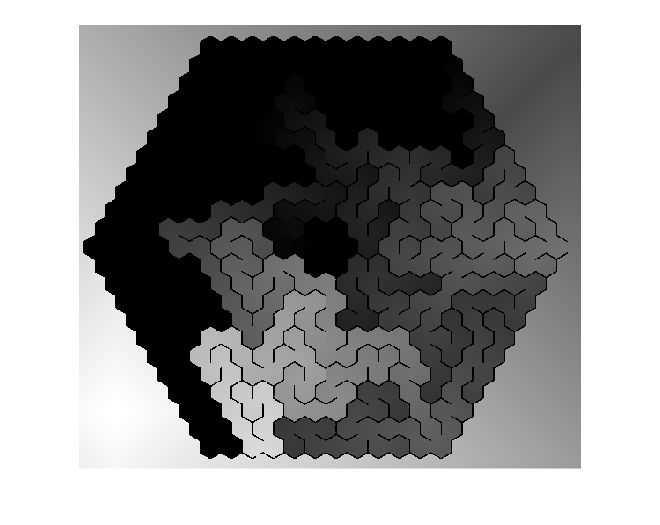

imshow(dist2,[]);

m = max(max(dist+dist2))

m = 1443

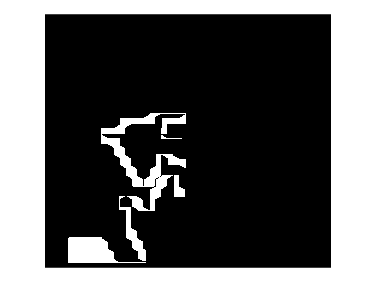

distmax = dist+dist2;
distmax = distmax == m;
imshow(distmax,[]);

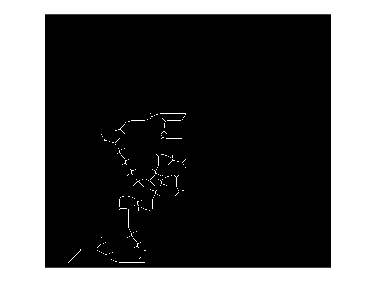

%skel
sk = bwmorph(distmax,"skel",inf);
imshow(sk);

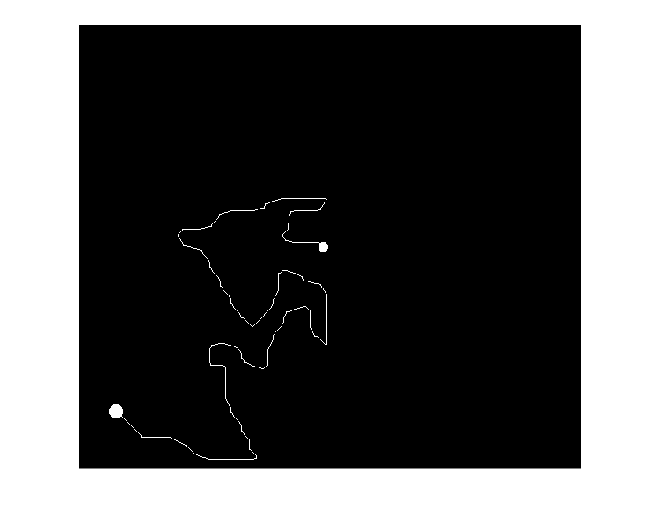


sk = bwmorph(sk|seed|greenDot,"spur",inf);
imshow(sk);

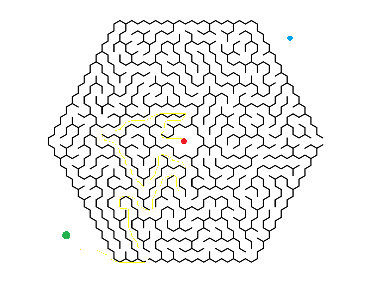

sk = sk-seed;
sk = sk-greenDot;
imFinal = imoverlay(I,sk,"yellow");
imshow(imFinal);